# Simulating Black Box Radar Attacks

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
config_folder_path = "./config_files/";
% config_name = "20MHz_USRP_revB.json";
% config_name = "20MHz_USRP_500us.json";
% config_name = "20MHz.json";
config_name = "100MHz.json";
% config_name = "1GHz.json";
% config_name = "4GHz.json";
simulator.load_params_from_JSON(config_folder_path + config_name);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();
% simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 4.04 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.37 us
	 ADC Samples: 			 128 
	 ADC Sample Rate: 		 7.38 MSps
	 Ramp End Time: 		 23.85 us
	 Chirp Tx Bandwidth: 		 96.31 MHz
	 Chirp Sampling Bandwidth: 	 70.04 MHz
	 ADC Sampling Period: 		 17.34 us
	 Chirp Cycle Time: 		 24.39 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 6.24 ms
Performance Specifications
	 Max Range 			 273.93 m
	 Range Resolution 		 2.14 m
	 Max Velocity 			 39.91 m/s
	 Velocity Resolution 		 0.31 m/s
FMCW Specifications
	 FMCW sampling rate 		 103.32 MHz
	 Downsampling factor 		 14
	 Sweep time 			 23.85 us
	 Samples per chirp 		 2520.00 
CFAR Detection Region
	 Range Detection Region 		 19.261 m to 252.528 m
	 Velocity Detection Region 		 -34.607 m/s to 34.919 m/s


## Initialize the Target

target_range = 80;
target_velocity = 7;
simulator.load_target_realistic(target_range,target_velocity);

## Initialize the Victim and Simulation Parameters

%specify the number of radar frames and chirps to compute
frames_to_compute = 10;

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%specify whether or not to record a move of the range-doppler plot
record_movie = true;

%specify whether or not the color bar for the Range-Doppler Response Plot
%should be enabled
enable_simplified_plots = false;

% for simulating USRP
if contains(config_name,"20MHz")
%     range_lims = [simulator.Victim.Radar_Signal_Processor.distance_detection_range(1),150];
    range_lims = [0,450];
    vel_lims = [-50,50];
    vel_exclusion_region = [-1,1];
else
    range_lims = [target_range - 20,target_range + 20];
    vel_lims = [-1*target_velocity - 20,-1 * target_velocity + 20];
    vel_exclusion_region = [-0.1,0.1];
end
frame_period_ms = simulator.Victim.FramePeriodicity_ms;



simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute, ...
    record_movie,range_lims,vel_lims,vel_exclusion_region,enable_simplified_plots);

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,frames_to_compute);
%set to change 1 to zero to disable

attack_type = "FN"; % or "FP"
if attack_type == "FN"
    attack_config = "range spoof - similar slope, velocity spoof - similar velocity";
elseif attack_type == "FP"
    attack_config = "target";
end

simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_config);


%if it is desired to specify a specific attack location
if attack_type == "FP"
    desired_pos = 79;
    desired_vel = -10;
    simulator.Attacker.Subsystem_attacking.set_desired_attack_location(desired_pos,desired_vel);
end

## Run the Simulation

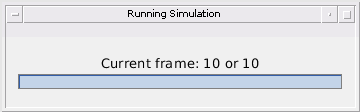

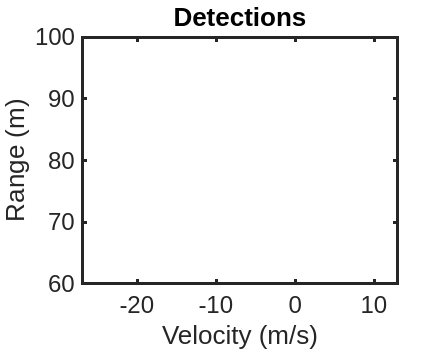

simulator.run_simulation_with_attack(frames_to_compute,true);

% you only want to run the simulation without an attack, use the following
% function
% simulator.run_simulation_no_attack(frames_to_compute,true);

## Results

Print out the detected ranges of objects in the simulation

%get the estimated ranges and velocities
range_detections = simulator.Victim.Radar_Signal_Processor.range_estimates

range_detections =    79.5649       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.3480       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.0961       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.2150       NaN       NaN       NaN       NaN       NaN       NaN       N

velocity_detections = simulator.Victim.Radar_Signal_Processor.velocity_estimates

velocity_detections =    -4.9927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9938       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9945       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9968       NaN       NaN       NaN       NaN       NaN       NaN     

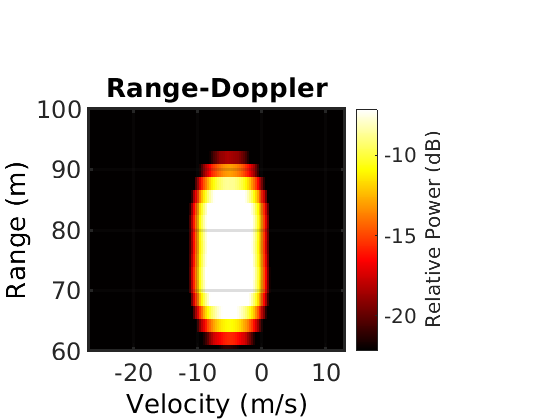

%play the movie for the range doppler
if record_movie
    file_name = "generated_plots/range_doppler.gif";
    characterization_functions.save_movie_to_gif(simulator.Victim.Radar_Signal_Processor.F_rngdop,1/(frame_period_ms*1e-3),file_name);
    characterization_functions.play_movie(simulator.Victim.Radar_Signal_Processor.F_rngdop,1/(frame_period_ms*1e-3));
end

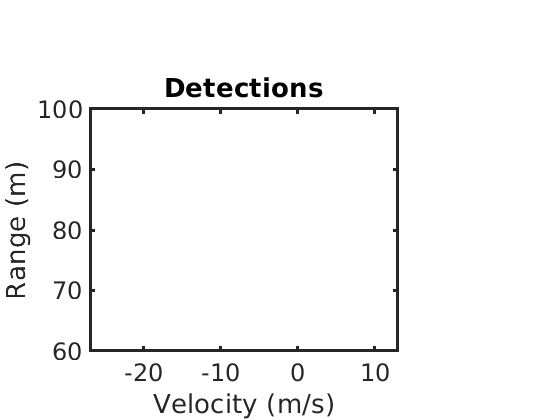

%play the movie for the range doppler
if record_movie
    file_name = "generated_plots/clusters.gif";
    characterization_functions.save_movie_to_gif(simulator.Victim.Radar_Signal_Processor.F_clusters,1/(frame_period_ms*1e-3),file_name);
    characterization_functions.play_movie(simulator.Victim.Radar_Signal_Processor.F_clusters,1/(frame_period_ms*1e-3));
end

#### Generating Clustering and Range-Doppler Response Figures

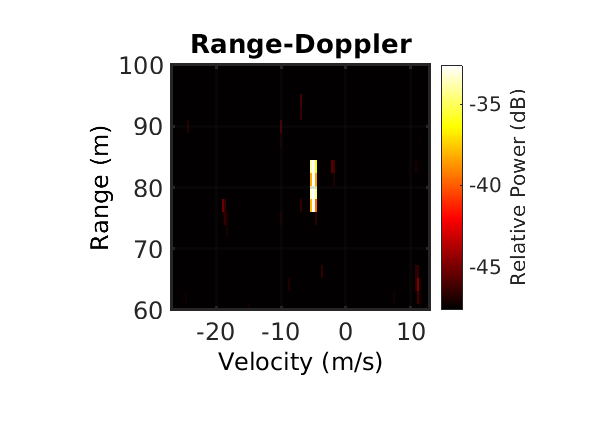

clf;
figure;
axis fill;
frame_to_plot = 4;

%plot and save the range doppler image    
[X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(frame_to_plot)));
imshow(X,map)
print('-r500',"generated_plots/range_doppler",'-dsvg')
print('-r500',"generated_plots/range_doppler",'-dpng')

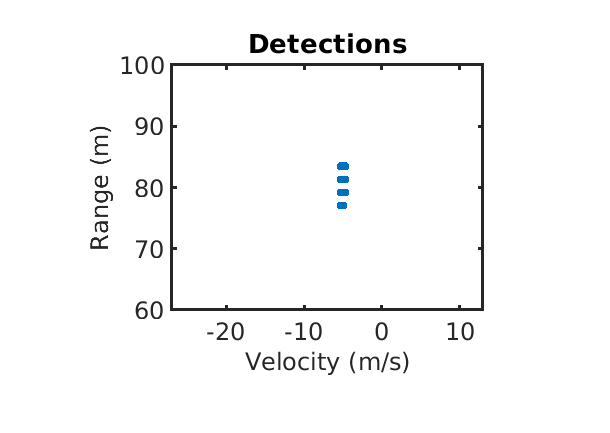

%plot and save the clustering image
[X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(frame_to_plot)));
imshow(X,map)
print('-r500',"generated_plots/clusters",'-dsvg')
print('-r500',"generated_plots/clusters",'-dpng')

Generate a subplot sampling of multiple frames for a preview of the movie

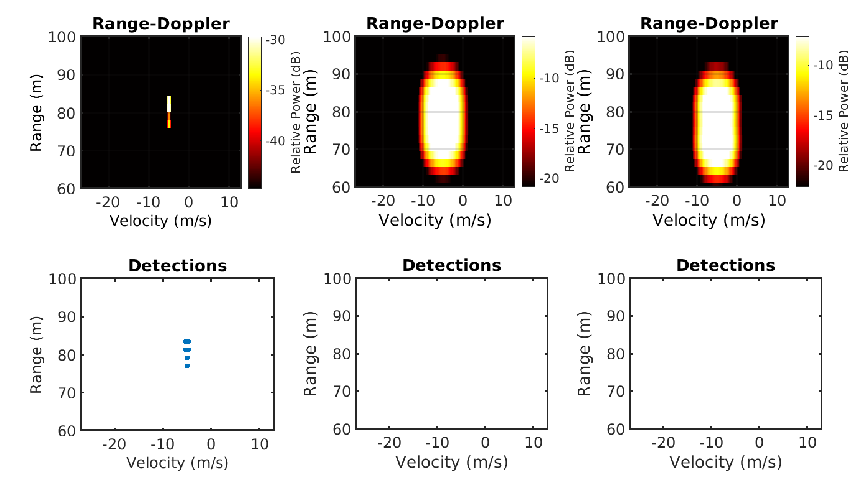

clf;
% figure('Position',[1,1,900,800]); %for 2 tiles
figure('Position',[1,1,1200,700]); %for 3 tiles
axis fill;
start_frame = 5;
middle_frame = 7;
end_frame = 9;
tiledlayout(2,3,TileSpacing="none",Padding="none")

    %subplot of the Doppler in the left column
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(start_frame)));
    imshow(X,map)
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(middle_frame)));
    imshow(X,map)
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(end_frame)));
    imshow(X,map)

    %subplot of the clustering in the right column
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(start_frame)));
    imshow(X,map)
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(middle_frame)));
    imshow(X,map)
    nexttile
    [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(end_frame)));
    imshow(X,map)

print('-r500',"generated_plots/attack_timeline",'-dsvg')
print('-r500',"generated_plots/attack_timeline",'-dpng')

## Evaluating CFAR Performance with surf plots

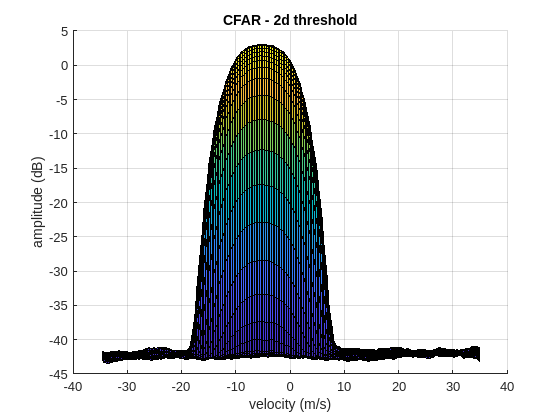

clf;
figure;

%evaluate the 2d CFAR detections for the desired frame
radar_cube = simulator.Victim.Radar_Signal_Processor.radar_cube;
[frame_resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);
% plotResponse(simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse,radar_cube)
CUT_indicies = simulator.Victim.Radar_Signal_Processor.CUT_indicies;

%configure the CFAR
release(simulator.Victim.Radar_Signal_Processor.CFARDetector2D);
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.ThresholdOutputPort = true;
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.OutputFormat ="CUT result";


%compute the CFAR
[detections,th] = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(frame_resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);

%determine range indicies in threshold detector
ranges = rnggrid(CUT_indicies(1,:)); %y
velocities = dopgrid(CUT_indicies(2,:)); %x


dopgrid_th = linspace(min(velocities), max(velocities),max(CUT_indicies(2,:)) - min(CUT_indicies(2,:) - 1));
rnggrid_th = linspace(min(ranges), max(ranges),max(CUT_indicies(1,:)) - min(CUT_indicies(1,:) - 1));
[X,Y] = meshgrid(dopgrid_th, rnggrid_th);

%convert the thresholds to db
th = (10 * log10(th));

th_surface = griddata(velocities,ranges,th,X,Y);
surf(X, Y, th_surface);
view(0,0);
title("CFAR - 2d threshold");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

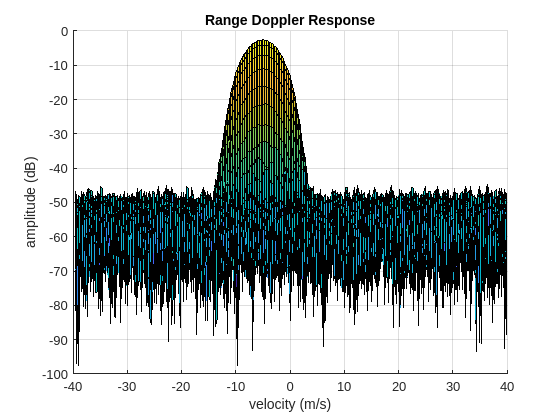


% convert the response to db
frame_resp = (10 * log10(abs(frame_resp).^(2)));
surf(dopgrid,rnggrid,frame_resp)
view(0,0);
title("Range Doppler Response");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

## Evaluating Range Performance

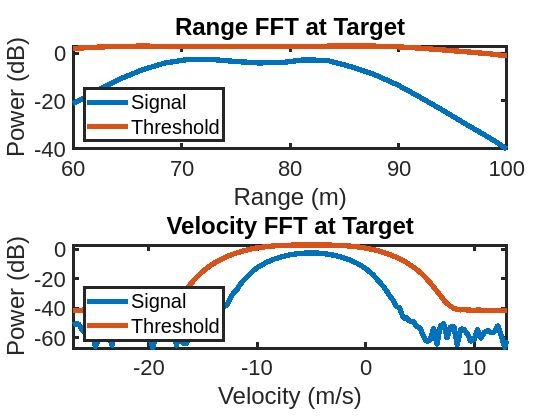

%find the maximum point
[M,I] = max(frame_resp,[],'all');
[rng_idx,vel_idx] = find(frame_resp == M);

%compute the indicies for the computed threshold
rng_idx_th = find(abs(rnggrid_th - rnggrid(rng_idx)) < 1e-4);
if isempty(rng_idx_th)
    rng_idx_th = 1;
end
vel_idx_th = find(abs(dopgrid_th - dopgrid(vel_idx)) < 1e-4);
if isempty(vel_idx_th)
    vel_idx_th = 1;
end

%plot range
rng_fft = frame_resp(:,vel_idx);
rng_th = th_surface(:,vel_idx_th);

font_size = 17;


subplot(2,1,1) 
plot(rnggrid,rng_fft,rnggrid_th,rng_th,"LineWidth",4.0)
xlim(range_lims)

title("Range FFT at Target","FontSize",font_size)
xlabel("Range (m)","FontSize",font_size)
ylabel("Power (dB)","FontSize",font_size)
ax = gca;
ax.FontSize = font_size;
ax.LineWidth = 2.0;
legend('Signal','Threshold','Location','Southwest')

%plot velocity
dop_fft = frame_resp(rng_idx,:);
dop_th = th_surface(rng_idx_th,:);

subplot(2,1,2) 
plot(dopgrid,dop_fft,dopgrid_th,dop_th, "lineWidth",4.0)
xlim(vel_lims)

font_size = 17;
title("Velocity FFT at Target","FontSize",font_size)
xlabel("Velocity (m/s)","FontSize",font_size)
ylabel("Power (dB)","FontSize",font_size)
legend('Signal','Threshold','Location','Southwest')
ax = gca;
ax.FontSize = font_size;
ax.LineWidth = 2.0;

%save the plots
% print('-r300',"generated_plots/CFAR_output",'-dsvg')
print('-r300',"generated_plots/CFAR_output",'-dpng')

Generate plot of IF signals

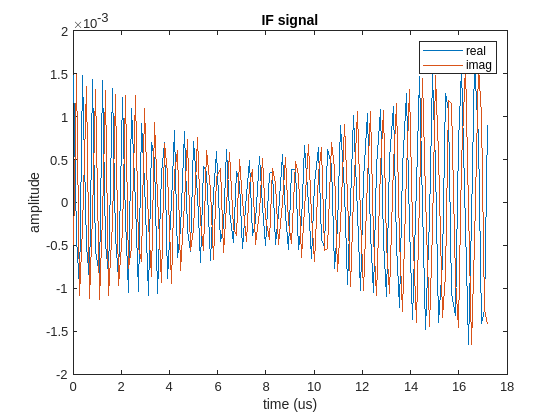

sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.radar_cube(:,1);
inter_sample_period = 1/simulator.Victim.ADC_SampleRate_MSps;
times = 0:inter_sample_period:(simulator.Victim.ADC_Samples - 1) * inter_sample_period;
clf;
plot(times,real(sampled_IF_sig),times, imag(sampled_IF_sig));
legend("real","imag")
xlabel("time (us)")
ylabel("amplitude")
title("IF signal")
print('-r300',"generated_plots/if_signal",'-dsvg')
print('-r300',"generated_plots/if_signal",'-dpng')

Plot a range FFT

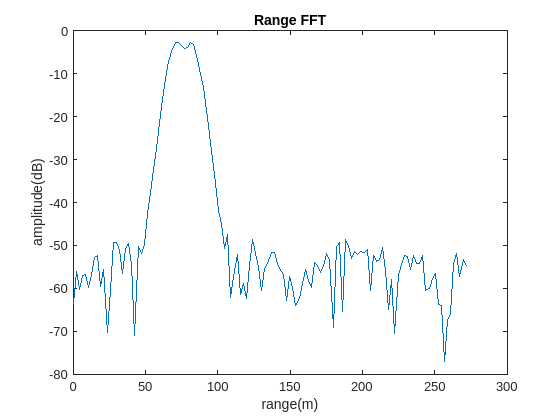

rng_fft = frame_resp(:,vel_idx);
% rng_fft = abs(fft(sampled_IF_sig));

plot(rnggrid,rng_fft)
title("range FFT at target")
xlabel("range(m)")
ylabel("amplitude(dB)")
title("Range FFT")
print('-r300',"generated_plots/Range_fft",'-dsvg')
print('-r300',"generated_plots/Range_fft",'-dpng')